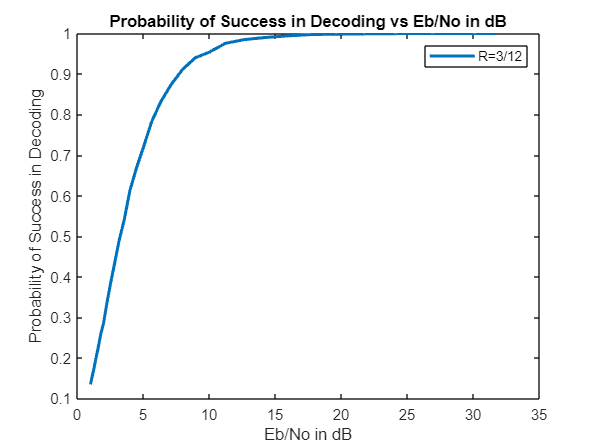



H = [1 0 0 0 0 1 0 1 0 1 0 0;
    1 0 0 1 1 0 0 0 0 0 1 0;
    0 1 0 0 1 0 1 0 1 0 0 0;
    0 0 1 0 0 1 0 0 0 0 1 1;
    0 0 1 0 0 0 1 1 0 0 0 1;
    0 1 0 0 1 0 0 0 1 0 1 0;
    1 0 0 1 0 0 1 0 0 1 0 0;
    0 1 0 0 0 1 0 1 0 1 0 0;
    0 0 1 1 0 0 0 0 1 0 0 1];
No_of_cols = length(H);
No_of_rows = height(H);

EbNodB = 0:0.5:15;
EbNo = 10.^(EbNodB./10);
code_rate=1/4;
transmit_msg= zeros(1,No_of_cols);
modulated_msg = 1 - 2*transmit_msg;
Number_of_sim = 10000;
iteration_max = 50;
sigma = sqrt(1./(2.*code_rate.*EbNo));
success_decoding_probability= zeros(1,length(EbNodB));
error_decoding_probability= zeros(1,length(EbNodB));
bit_error_decoding_probability = zeros(1,length(EbNodB));
for  V = 1:1:length(EbNodB)
    success = 0;
    error =0;
    for U= 1:1:Number_of_sim
        flag = 0;
        received_msg = modulated_msg + sigma(1,V)*randn(1,No_of_cols);
        r_likelihood_ratio = (2*received_msg)./(sigma(1,V)*sigma(1,V));
        L=zeros(size(H));
        [rows, cols] =size(H);

        total_likelihood_ratio = zeros(1,cols);
        for i=1:rows
            for j=1:cols
                if H(i, j) == 1
                    L(i, j) = r_likelihood_ratio(j);
                end
            end
        end

        for it= 1:1:iteration_max
            S = prod((2*(L>=0)-1), 2);
            S = S';
            L_abs = abs(L);
            for i=1:1:rows
                row_value = L_abs(i, :);
                [min_val_1, min_index, min_val_2] = calc_row_min(row_value);
                for j = 1:1:cols
                    if L(i,j) ~= 0
                        if j == min_index
                            L(i,j)=min_val_2*(2*(L(i,j)>=0)-1)*S(1,i);
                        else
                            L(i,j)=min_val_1*(2*(L(i,j)>=0)-1)*S(1,i);
                        end
                    end
                end


            end
            total_likelihood_ratio = sum(L);
            for i=1:rows
                for j=1:cols
                    if H(i, j) == 1
                        L(i, j) = total_likelihood_ratio(j)-L(i,j);
                    end
                end
            end
            decoded_msg = total_likelihood_ratio < 0;
            comparing = mod(decoded_msg+transmit_msg, 2);
            if sum(comparing,2)==0;
                flag =1;
                break;
            end
        end

        success = success + flag;
        error = error + sum(comparing, 2);

    end
    success_decoding_probability(1,V) = success/Number_of_sim;
    error_decoding_probability(1,V) = 1 - success_decoding_probability(1,V);
    bit_error_decoding_probability(1,V) = error/(length(transmit_msg)*Number_of_sim);

end


figure
plot(EbNo,success_decoding_probability, 'LineWidth', 2);
xlabel('Eb/No in dB');
ylabel('Probability of Success in Decoding');
title('Probability of Success in Decoding vs Eb/No in dB');
legend('R=3/12');

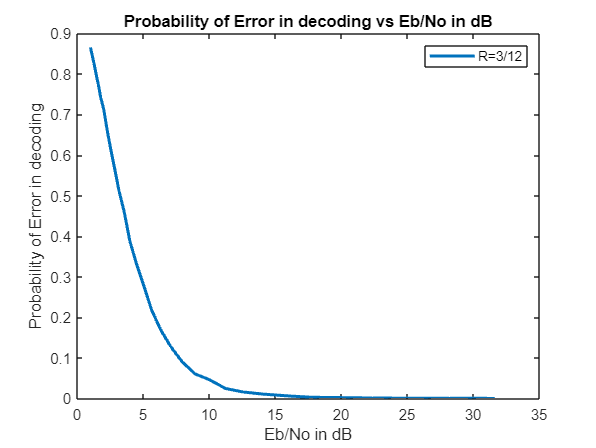



figure;
plot(EbNo,error_decoding_probability, 'LineWidth', 2);
xlabel('Eb/No in dB');
ylabel('Probability of Error in decoding');
title('Probability of Error in decoding vs Eb/No in dB');
legend('R=3/12');

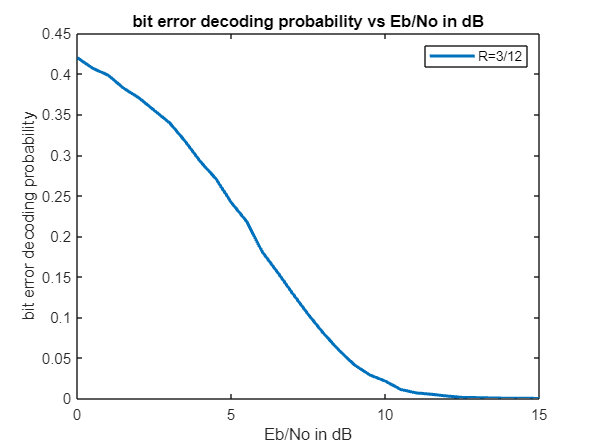


figure
plot(EbNodB, bit_error_decoding_probability, 'LineWidth', 2);
xlabel('Eb/No in dB');
ylabel('bit error decoding probability');
title('bit error decoding probability vs Eb/No in dB');
legend('R=3/12');

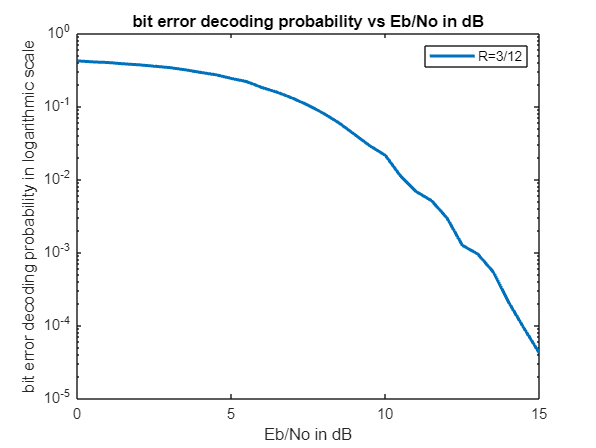


figure
semilogy(EbNodB, bit_error_decoding_probability, 'LineWidth', 2);
xlabel('Eb/No in dB');
ylabel('bit error decoding probability in logarithmic scale');
title('bit error decoding probability vs Eb/No in dB');
legend('R=3/12');

function [min_val_1, min_index, min_val_2] = calc_row_min(row_value)

min_val_1 = intmax('int64');
min_val_2 = intmax('int64');
min_index = 1;

for i = 1:1:length(row_value)
    if row_value(1,i) ~= 0
        if row_value(1,i) <= min_val_1
            min_val_1 = row_value(1,i);
            min_index = i;
        end
    end
end
for i = 1:1:length(row_value)
    if row_value(1,i) <= min_val_2
        if row_value(1,i) ~= 0
            if i ~= min_index
                min_val_2 = row_value(1,i);
            end
        end
    end
end
end
